# Oscillometric model 

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter5/Babbs_Model'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=1; % saving the figures in a file

## Introduction

This notebook provides introduction to models and algorithms for blood pressure measurements. 

Figure below represents the cross-section of the cuff, arm and artery system. The grey circle is the cross-section of the upper arm with the bone and the artery shown inside.  The outermost black circle represents the cuff that is wrapped around the arm. Cuff pressure is denoted as$p_c(t)$. The internal pressure in the artery is denoted as $p_a(t)$. The signal at the output of the pressure transducer represent the pressure obtained during cuff deflation (deflation curve). Small pulses are supperimposed on the deflation curve and these pulses are extracted and amplified in the bottom right corner of Figure. They form a waveform called the oscillometric waveform. The envelope of the oscillometric waveform is called oscillometric waveform envelope. Systolic blood pressure (SBP) and diastolic blood pressure (DBP) are obtained by processing the oscillometric envelope using oscillometric algorithms.

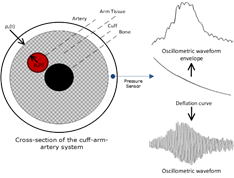

Our goal is to compute SBP and DBP from the oscillometric waveform. In order to do that, we will present first a physiological and system model that explains how the blood pressure  data is generated. Next, we will present the algorithm. Therefore, the model includes:

- Model of the cuff and the artery that is used to generate the oscillometric waveform

- Oscillometric algorithms

- Analysis of the accuracy of the oscillometric algorithm

## Arm-Artery System Model

The arm-artery model is based on the paper: 

[1] C. F. Babbs, “[Oscillometric measurement of systolic and diastolic blood pressures validated in a physiologic mathematical model](https://biomedical-engineering-online.biomedcentral.com/articles/10.1186/1475-925X-11-56),“  BioMedical Engineering OnLine, Vol. 11, no: 56, 2012. 

The model introduces transmural pressure $P_t (t)= P_a (t)–P_c (t)$ that represents the pressure of both sides of the arterial wall. When the cuff is placed around the upper arm and the pressure is applied, the volume of the artery reduces. The volume of the artery is related to the pressure as

$V_a \left(t\right)={\left\{\begin{array}{c}
V_{a0} e^{ap_t \left(t\right)} ,\ for\ P_t \left(t\right)<0\\
\left.V_{a0} \left\lbrack 1+\frac{a}{b}{\left(1-e^{-bP_t \left(t\right)} \right)}\right\rbrack ,\ for\ P_t \left(t\right)\ge 0
\end{array}\right)}$ (1)

During cuff deflation, total pressure is computed as the sum of the decreasing cuff pressure with the rate r, and superimposed variations due to arterial volume Va(t) changes in each cardiac cycle: 

$P\left(t\right)=P_0 -rt+P_{ath} +V_a \left(t\right)/C_{cuff} \left(t\right)$ (2)

$C_{cuff} \left(t\right)$is the compliance of the cuff and it can be modeled as $C_{cuff} \ \left(t\right)=V_0 /\left(P_0 -rt+P_{ath} \right)$, where $P_{ath}$ is the athnospheric pressure and $V_0$ is the maximum volume of hte cuff.                       

Next, we will introduce the parameters of the model including:

Pressure parameters and signals (with the time index t):

- systolic pressure: SBP

- diastolic pressure: DBP

- pulse pressure: PP= SBP-DBP

- arterial pressure: Pa(t)

- transmural pressure: Pt(t) where $Pt=Pa-(P0-rate\cdot t)$;

Deflation and cuff parameters

- pressure up the which the duff is inflated: P0=SBP+30

- rate of cuff deflation: rate (r)

- volume of the cuff: V0

Artery parameters

- radius of the artery in cm: r 

- length of the artery covered by the cuff in cm: L

- resting artery volume: $Va0=3.14 \cdot r^2 \cdot 
L$

- the volume of the artery $V_a \left(t\right)$ vs transmural pressure  as in (1) 

- compliance constants of the arterial model: a and b 

- heart rate in Hz: heart_rate

### Matlab model of the Arm-Artery System

Several parameters that are not related to the model will be introduced first:

clear_all_but('SAVE_FLAG')
delta_T=0.005;
fs=1/delta_T;
plotting=1;

We will first simulate the signal for normal values of blood rpessure of SBP=120 mmHg and DBP=80 mmHg.


SBP=120;
DBP=80;
%Computing the parameters
PP= SBP-DBP; % pulse pressure
P0=SBP+30; % start of cuff deflation
heart_rate=1; % in Hz

**Arterial pulse Pa(t)** is modeled as Fourier series based on [1]. We also compute its derivative dP_dt. Please note that the shape does not eactly follows the arterial pulse pressure morphology. 

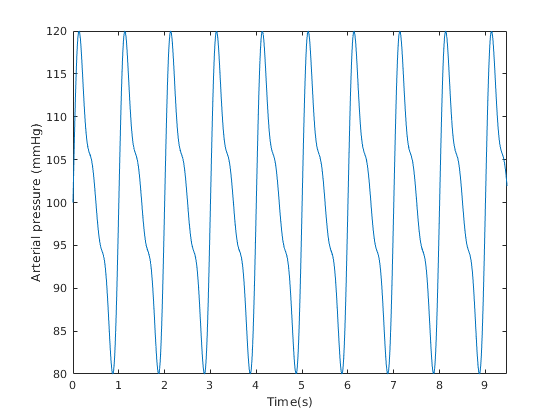

% Model of the arterial pulse and its derivative
delta_T=1/fs;
t=0:delta_T:55;
omega=2*pi*heart_rate;
Pa=DBP+0.5*PP+0.36*PP*(sin(omega*t)+0.5*sin(2*omega*t)+0.25*sin(3*omega*t));
dP_dt=0.36*PP*omega*(cos(omega*t)+cos(2*omega*t)+0.75*cos(3*omega*t));
if plotting ==1
    figure; plot(t,Pa)
    xlabel("Time(s)")
    ylabel("Arterial pressure (mmHg)")
    xlim([0.00 9.47])
    ylim([80 120.0])
end

Next, we will show** arterial volume** against the transmural pressure for several different patient conditions.

Compliance constants a and b allow us to simulate different patient conditions. Increasing a  and b  in proportion results in larger volume changes for a given pressure change and therefore larger values of a  and b  can be used to represent a more compliant artery. Decreasing  a and b in proportion reduces the volume change for a given pressure change and so that smaller values of a  and b  represent a stiffer artery. Increasing the ratio $a/b
$  represents a greater maximal distension. Decreasing the ratio a/b represents a smaller maximal distension. We will analyze the shape of the Va(t) vs Pt(t) curve for the cases of: normal arterial stifness, stiff artery, artery with hhalf normal stifness and the artery with increased maximal distension. Please note that the blood pressure should normally increase when the artery is stiffer - however in this example we will keep SBP and DBP the same and only chage complieance parameters a and b.

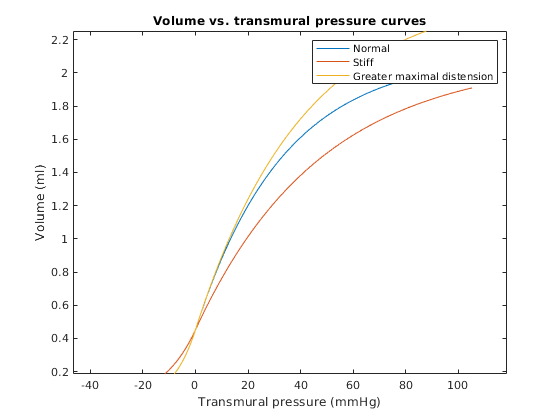

ArteryProp.a(1)=0.11; ArteryProp.b(1)=0.03; ArteryProp.c(1)="Normal";
ArteryProp.a(2)=0.076; ArteryProp.b(2)=0.021; ArteryProp.c(2)="Stiff";
%ArteryProp.a(3)=0.158; ArteryProp.b(3)=0.0432; ArteryProp.c(3)="Half normal";
ArteryProp.a(3)=0.11; ArteryProp.b(3)=0.0244; ArteryProp.c(3)="Greater maximal distension";
r=0.12;     % radius of the artery in cm
L=10;       % length of the artery covered by the cuff in cm
Va0=3.14*(r)^2*L; %The resting artery volume
rate=2.5;   % Deflation rate in mmHg/s
legend_arter=[];
% Volume vs transmural pressure - equation (4) from the paper [1]
for j=1:length(ArteryProp.a)
    a=ArteryProp.a(j);
    b=ArteryProp.b(j);
    for i=1:length(t)
        Pt(i)=Pa(i)-P0+rate*t(i);
        if Pt(i)<0
            Va(i,j)=Va0*exp(a*Pt(i));
        else
            Va(i,j)=Va0*(1+(1-exp(-b*Pt(i)))*a/b);
        end
    end
    if plotting ==1
        plot(Pt,Va(:,j))
        legend_arter=[legend_arter ArteryProp.c(j)];
        hold on
    end
end
legend(legend_arter)
ylabel("Volume (ml)")
xlabel("Transmural pressure (mmHg)")
title('Volume vs. transmural pressure curves')
annonation_save('',"Fig5.5.jpg", SAVE_FLAG);

Let us now show how the transmural pressure and the volume change over time. Let us consider normal arteries first. 

**Excersize**: Plot the graph below for different cases of arterial stifness.  Explain the results.

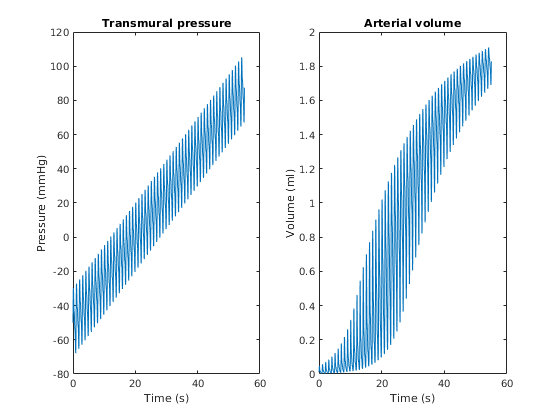

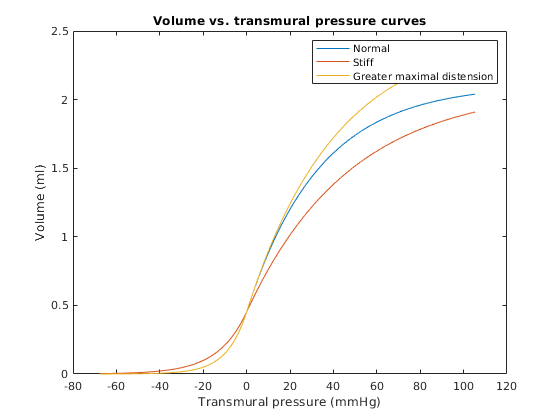

j=2; % choose 1 for normal, 2 for stiff, 3 for half normal and 4 for the increased maximal distension
a=ArteryProp.a(j);
b=ArteryProp.b(j);
if plotting ==1
    figure
    subplot 121
    plot(t, Pt)
    xlabel("Time (s)")
    ylabel("Pressure (mmHg)")
    title("Transmural pressure")
    subplot 122
    plot(t, Va(:,j))
    xlabel("Time (s)")
    ylabel("Volume (ml)")
    title("Arterial volume")
    %legend(ArteryProp.c(j));
  
end
exportgraphics(gcf,"Fig5.6.jpg", 'Resolution',600)

Calculation of total blood pressure in (2) is simplified version of the model presented in [1]. That model include the relationship between the changes of the total pressure and changes in the volume of the artery. Therefore, for modeling pressure signal over time using (2) please set PRESSURE_VOLUME_CHANGES=0. For modeling pressure signal using formulas (1) and (6) from [1] please set PRESSURE_VOLUME_CHANGES=1.

[P, Pa]=model_Babbs(a,b,SBP, DBP, fs, 1);

## Oscillometric algorithms

Traditional algorithm for estimating blood pressure based on oscillometric method includes several steps such as: 

- Extracting oscillometric waveform (OMW).

- Extracting features from the pulses – these features over time are called oscillometric pulse indices (OPI).

- Interpolating OPIs to obtain the envelope and smoothing the envelope. The envelope of an oscillating signal is defined as a smooth curve outlining its extremes.

- Estimating MAP, SBP and DBP using the oscillometric algorithm. 

1. The first part of the oscillometric algorithms is extracting the OMW. The output is the cuff pressure without thearterial based oscillations and oscillometric waveform. 

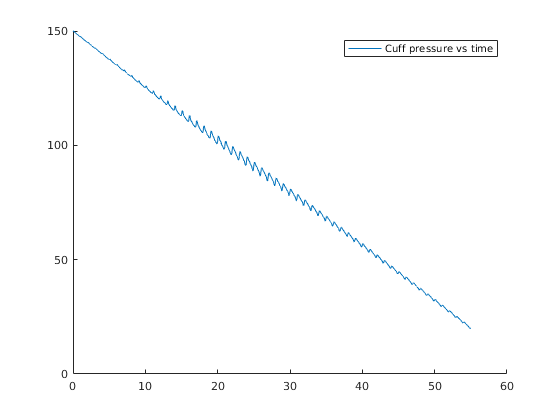

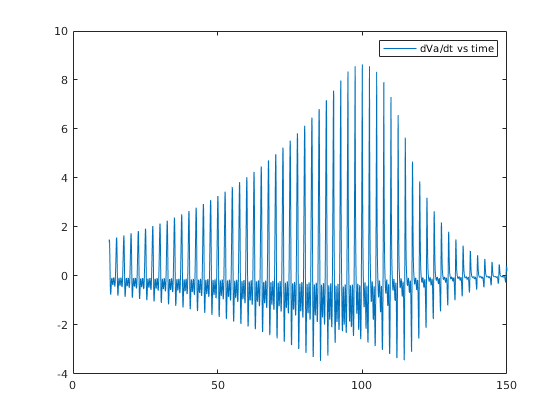

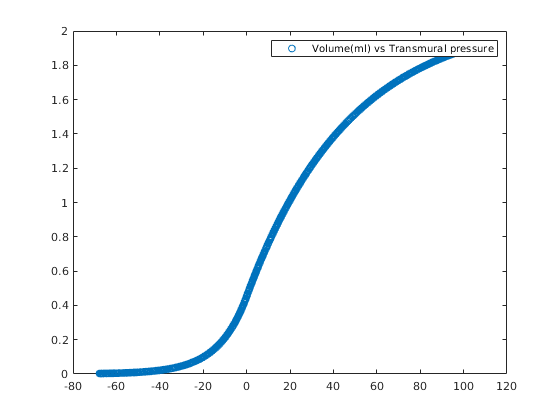

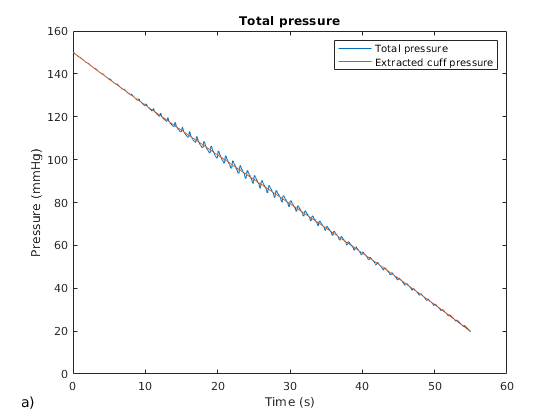

[cp,omw] = extract_omw(P, fs);
if plotting ==1
    figure,
    plot(t,P) % and another way is manual integration
    hold on, plot(t, cp)
    xlabel("Time (s)"), ylabel("Pressure (mmHg)"), legend('Total pressure', 'Extracted cuff pressure')
end
title ("Total pressure")
annonation_save('a)',"Fig5.7a.jpg", SAVE_FLAG);

2. and 3. Next steps include estimating the envelope. 

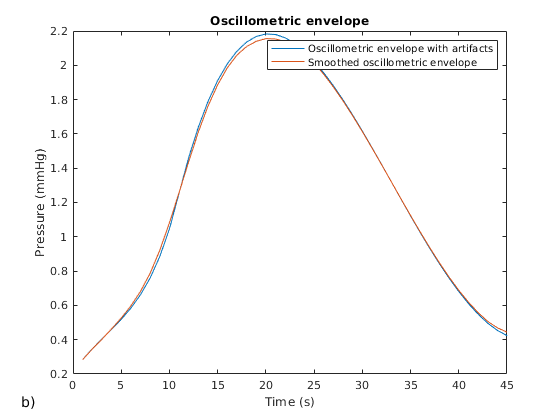

[omwe, peak_ind] = envelope_detection(cp, omw, fs);

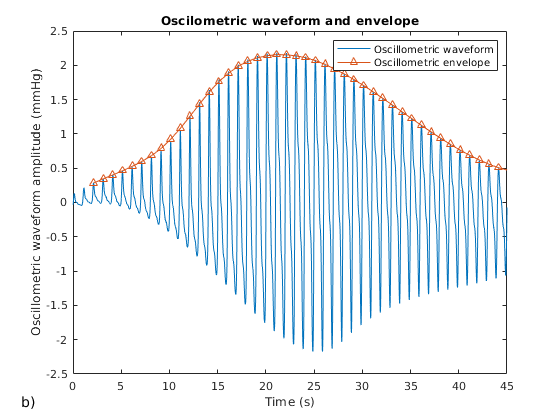

if plotting ==1
    figure
    plot(t,omw)
    hold on
    plot(t(peak_ind), omwe, '^-')
    xlabel("Time (s)"), ylabel("Oscillometric waveform amplitude (mmHg)")
    xlim([0,45])
    legend('Oscillometric waveform', 'Oscillometric envelope')
end    
title('Oscilometric waveform and envelope')
annonation_save('b)',"Fig5.7b.jpg", SAVE_FLAG);

%Fig 6.2
figure
subplot 311
if plotting ==1
plot(t,P) % and another way is manual integration
xlabel("Time (s)"), ylabel("Pressure (mmHg)"), title('Total pressure')
xlim([0,45])
end
subplot 312
if plotting ==1
plot(t,omw)
xlabel("Time (s)"), ylabel("Pressure (mmHg)")
xlim([0,45])
title('Oscillometric waveform')
end
if plotting ==1
subplot 313
plot(t(peak_ind), omwe)
xlabel("Time (s)"), ylabel("Pressure (mmHg)")
xlim([0,45])
title('Oscillometric envelope')
end
annonation_save('b)',"Fig5.2b.jpg", SAVE_FLAG);

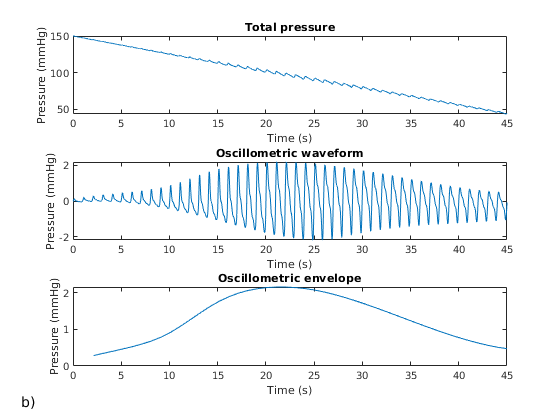

exportgraphics(gcf,"Fig5.2b.jpg", 'Resolution',600)

**Exercise: **Uncoment  the line in the envelope detection algorithm that says "Form the envelope based only on maximums" and comment the line after "Form envelope based on peak to peak". Explore the effect of finding the envelope based only on the maximum of the pulse vs peak-to-peak.

---

4. For the last step, we will consider two algorithms:

- Maxumum amplitude algorithm that is based on fixed coeffients

- Maximum slope algorithm which estimate is based on the position of the maximum slope on the diastolic and systolic part of the oscillometric envelope.

### Maximum amplitude algorithm (MAA)

MAA is based on finding the time instant of the maximum of the envelope and then mapping the time instant to the cuff deflation waveform and reading the MAP. This is shown in the figure below. The time instance of SBP is obtained by finding a position on the oscilometric envelope where the maximum of the oscillometric envelope multiplied with the pre-defined coefficient intercepts the oscillometric envelope. Then, this maximum is mapped to the cuff pressure curve. Similar procedure is performed for finding diastolic presure. 

coef(1)=0.6;
coef(2)=0.65;
[BP] = bp_max_amplitude(cp, coef, fs, omwe, peak_ind);
fprintf('Maximum amplitude algorithm')

Maximum amplitude algorithm

fprintf('SBP=%f, SBP Error=%f', BP(1), BP(1)-SBP)

SBP=118.070126, SBP Error=-1.929874

fprintf('DBP=%f, DBP Error=%f', BP(2), BP(2)-DBP)

DBP=72.303709, DBP Error=-7.696291

fprintf('MAP=%f, MAP Error=%f', BP(3), BP(3)-mean(Pa))

MAP=99.605427, MAP Error=-0.394573

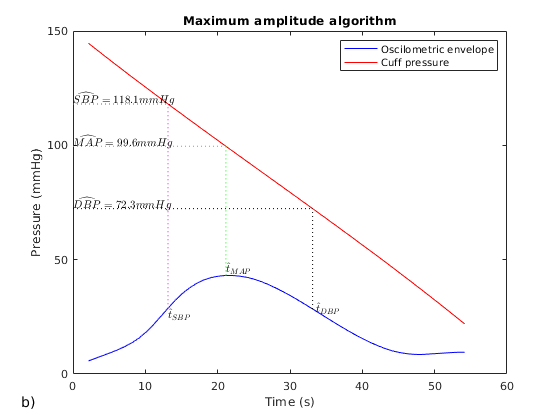

if plotting ==1
    [m,ind]=max(omwe);
    i1=find(m*coef(1)<omwe);
    i2=find(m*coef(2)<omwe);
     
    figure
    tspan = 1/fs:1/fs:length(cp)/fs;
    a1=plot(tspan(peak_ind),omwe*20, 'b'); % we are just rescaling the envelope so that it is easier to visualize
    hold on
    a2=plot(tspan(peak_ind),cp(peak_ind), 'r');
    a3=plot([0 tspan(peak_ind(ind))],[BP(3) BP(3)], 'g','LineStyle',":");
    plot([tspan(peak_ind(ind)) tspan(peak_ind(ind))],[omwe(ind)*20 BP(3)], 'g','LineStyle',":")
    text(0,BP(3)+2,sprintf('$$\\widehat{MAP}=%.1f mmHg$$',BP(3) ), 'Interpreter', 'latex') 
    text(tspan(peak_ind(ind)), omwe(ind)*20+3, sprintf('$$\\hat{t}_{MAP}$$'), 'Interpreter', 'latex')
    
    a4=plot([0 tspan(peak_ind(i1(1)))],[BP(1) BP(1)], 'm','LineStyle',":");
    plot([tspan(peak_ind(i1(1))) tspan(peak_ind(i1(1)))],[omwe(i1(1))*20 BP(1)], 'm','LineStyle',":")
    text(tspan(peak_ind(i1(1))), omwe(i1(1))*20-3, sprintf('$$\\hat{t}_{SBP}$$'), 'Interpreter', 'latex')
    text(0,BP(1)+2,sprintf('$$\\widehat{SBP}=%.1f mmHg$$',BP(1) ), 'Interpreter', 'latex') 
    
    a5=plot([0 tspan(peak_ind(i2(end)))],[BP(2) BP(2)], 'k','LineStyle',":");
    plot([tspan(peak_ind(i2(end))) tspan(peak_ind(i2(end)))],[omwe(i2(end))*20 BP(2)], 'k','LineStyle',":")
    text(tspan(peak_ind(i2(end)))+0.5, omwe(i2(end))*20, sprintf('$$\\hat{t}_{DBP}$$'), 'Interpreter', 'latex')
    text(0,BP(2)+2,sprintf('$$\\widehat{DBP}=%.1f mmHg$$',BP(2) ), 'Interpreter', 'latex') 
    xlabel('Time (s)')
    ylabel('Pressure (mmHg)')
    legend('Oscilometric envelope', 'Cuff pressure')
    title('Maximum amplitude algorithm')
    
end
annonation_save('b)',"Fig5.9b.jpg", SAVE_FLAG);

### Maximum Slope algorithm (MSE)

Unlike the previous algorithm, the maximum slope algorithm considers the slope of the envelope rather than the heights. Here, the systolic point is found as the point on the envelope where the slope of the envelope is at its maximum and the diastolic point is where the slope of the envelope is at its minimum. These two points can be found by taking the derivative of the signal. Since the derivative represents the slope of the line tangent to each point on the signal, the point where slope is maximum also correspond to the maximum of the derivative signal and the point where slope is minimum also corresponds to the minimum of the derivative signal. 

[BP, index] = bp_max_slope(cp, fs, omwe, peak_ind);
fprintf('Maximum slope algorithm')

Maximum slope algorithm

fprintf('SBP=%f, SBP Error=%f', BP(1), BP(1)-SBP)

SBP=118.070126, SBP Error=-1.929874

fprintf('DBP=%f, DBP Error=%f', BP(2), BP(2)-DBP)

DBP=67.718446, DBP Error=-12.281554

fprintf('MAP=%f, MAP Error=%f', BP(3), BP(3)-mean(Pa))

MAP=99.605427, MAP Error=-0.394573

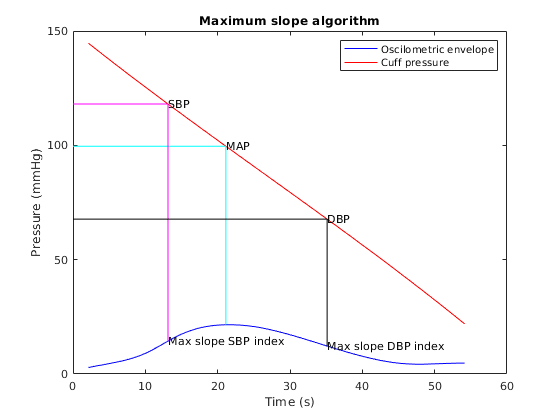

if plotting ==1   
    figure
    tspan = 1/fs:1/fs:length(cp)/fs;
    a1=plot(tspan(peak_ind),omwe*10, 'b'); % we are just rescaling the envelope so that it is easier to visualize
    hold on
    a2=plot(tspan(peak_ind),cp(peak_ind), 'r');
    a3=plot([0 tspan(peak_ind(index(3)))],[BP(3) BP(3)], 'c');
    plot([tspan(peak_ind(index(3))) tspan(peak_ind(index(3)))],[omwe(index(3))*10 BP(3)], 'c')
    text(tspan(peak_ind(index(3))), BP(3), "MAP")
    
    a4=plot([0 tspan(peak_ind(index(1)))],[BP(1) BP(1)], 'm');
    plot([tspan(peak_ind(index(1))) tspan(peak_ind(index(1)))],[omwe(index(1))*10 BP(1)], 'm')
    text(tspan(peak_ind(index(1))), BP(1), "SBP")
    text(tspan(peak_ind(index(1))), omwe(index(1))*10, "Max slope SBP index")

    a5=plot([0 tspan(peak_ind(index(2)))],[BP(2) BP(2)], 'k');
    plot([tspan(peak_ind(index(2))) tspan(peak_ind(index(2)))],[omwe(index(2))*10 BP(2)], 'k')
    text(tspan(peak_ind(index(2))), BP(2), "DBP")
    text(tspan(peak_ind(index(2))), omwe(index(2))*10, "Max slope DBP index")
    
    xlabel('Time (s)')
    ylabel('Pressure (mmHg)')
    legend('Oscilometric envelope', 'Cuff pressure')
    title('Maximum slope algorithm')
end

**Exercise**: Evaluate how performance of blood pressure estimation algorithms depend on the arterial stifness. Modify the compliance parameters by changing j. What is the problem with fixed coefficients of the maximum amplitude algorithms?

**Exercise: **Fitting in the function extract_omw is done using third order polinomial. However, the pressure waveform seems almost linear. Explore the effects of the first order curve fitting on the results. Explore other methods for curve fitting - please see "Comparison of Algorithms for Oscillometric Blood Pressure Estimation" by Simu Chen at [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING/tree/master/Blood%20Pressure](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING/tree/master/Blood%20Pressure) 

## Motion artifacts

Impulse artifact can be simulated by the *sinc* function in discrete domain as $a_{imp} {\left(n\right)}=m\cdot sin\left(\pi nT_s /\eta \right)/\left(\pi nT_s \right)$. The central lobe of the *sinc* function can be used as an impulse artifact and was added to the cuff pressure signal. The duration of the artifact is determined by  $\eta$. We selected  $\eta$ =1.5 resulting in about 3 s long movement artifacts. The amplitude of the movement artifact is  m. This type of artifact could be due to motion of an elbow, for example, during the oscillometric measurement. Similar motion artifact model can be applied to other biomedical signals such as the PPG with some modifications in the amplitude and duration. 

motion=1;
% Generate motion artifacts
t1=-500*delta_T:delta_T:500*delta_T;
eta=1.5;
motion_signal=5*sin(pi*t1/eta)./(pi*t1);
motion_signal(501)=0.5*(motion_signal(500)+motion_signal(502));

Now, let us add the motion signal to the total pressure signal a the random point in time in the interval between 5s and 45s.

if motion==1
    z=zeros(1,length(P));
    start=5*fs+floor(45*fs*rand(1));
    z(start:start+length(motion_signal)-1)=motion_signal;
    P=P+z+0.4*randn(1,length(P));
end

Let us plot the pressure signal together with added motion artifact.

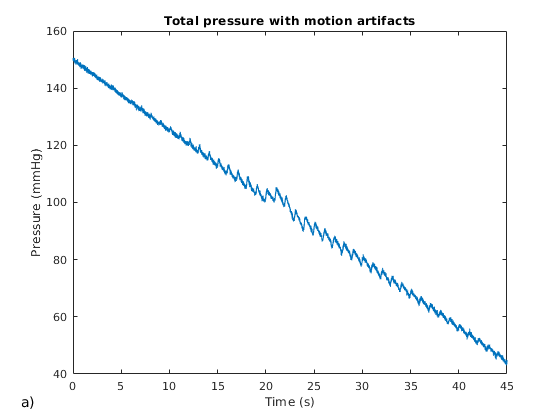

if plotting ==1
    figure,
    plot(t,P) % and another way is manual integration
    title('Total pressure with motion artifacts')
    xlabel("Time (s)"), ylabel("Pressure (mmHg)")
    xlim([0,45])

end
annonation_save('a)',"Fig5.13a.jpg", SAVE_FLAG);

Let us run the algorithms and estimate blood pressure

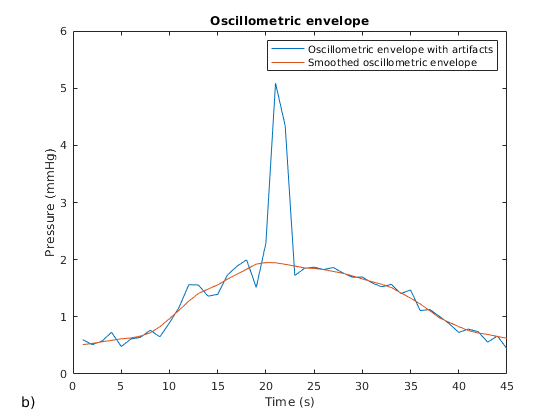

[cp,omw] = extract_omw(P, fs);
[omwe, peak_ind] = envelope_detection(cp, omw, fs);

Maximum amplitude algorithm

[BP] = bp_max_amplitude(cp, coef, fs, omwe, peak_ind);
fprintf('Maximum amplitude algorithm')

Maximum amplitude algorithm

fprintf('SBP=%f, SBP Error=%f', BP(1), BP(1)-SBP)

SBP=120.597900, SBP Error=0.597900

fprintf('DBP=%f, DBP Error=%f', BP(2), BP(2)-DBP)

DBP=67.840337, DBP Error=-12.159663

fprintf('MAP=%f, MAP Error=%f', BP(3), BP(3)-mean(Pa))

MAP=102.119047, MAP Error=2.119047

Maximum slope algorithm


[BP, index] = bp_max_slope(cp, fs, omwe, peak_ind);
fprintf('Maximum slope algorithm')

Maximum slope algorithm

fprintf('SBP=%f, SBP Error=%f', BP(1), BP(1)-SBP)

SBP=122.998742, SBP Error=2.998742

fprintf('DBP=%f, DBP Error=%f', BP(2), BP(2)-DBP)

DBP=65.465749, DBP Error=-14.534251

fprintf('MAP=%f, MAP Error=%f', BP(3), BP(3)-mean(Pa))

MAP=102.119047, MAP Error=2.119047

**Exercise**: Evaluate how motion artifacts affect blood pressure. Plot the oscilometric envelope with motion artifacts. Evaluate if the postion of motion artifacts in time affect the estimates of SBP and DBP. What happens if MAP gets estimated incorrectly - how does that affect estimates of SBP and DBP?

## Evaluating performace while varying blood pressure and compliance parameters

We will run blood pressure algorithm for 100 different values of SBP, DBP and parameters a and b. We know that compliance and blood pressure have negative correlation. We just assume some values for the negative correlation coefficient - these values can be changed after analyzing real data.

motion=1;
mu=[140 80 0.09 0.027];
sigma=[10^2 0.2*10*5 -0.6*10*0.02 -0.6*10*0.004; 0.2*10*5 5^2 -0.3*5*0.02 -0.3*5*0.004; -0.6*10*0.02 -0.3*5*0.02 0.02^2 0.75*0.02*0.004; -0.6*10*0.004 -0.3*5*0.004 0.75*0.02*0.004 0.004^2];
rng(125)  % For reproducibility
R = mvnrnd(mu,sigma,100);

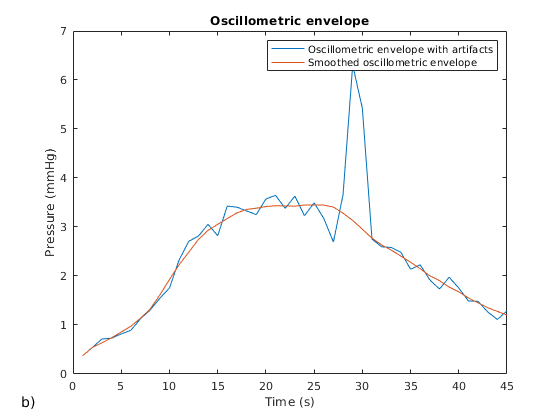

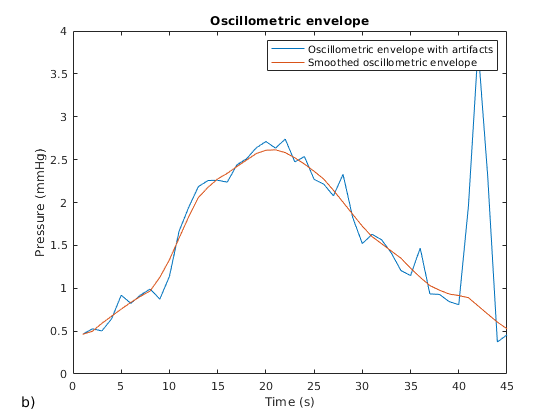

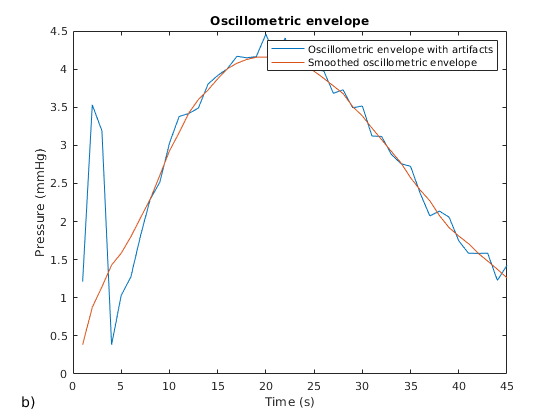

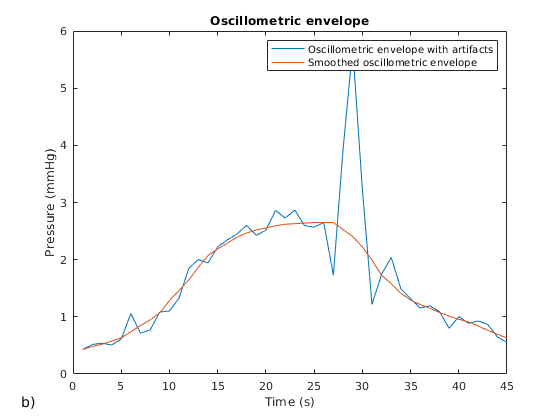

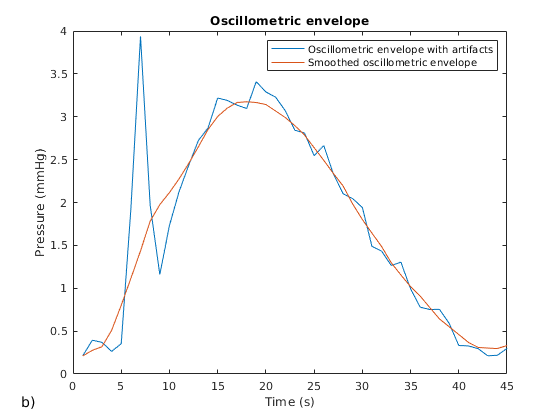

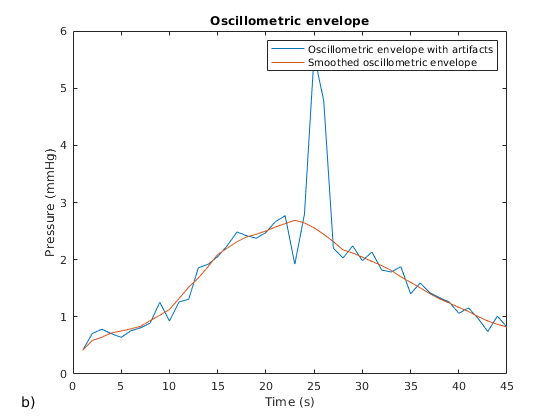

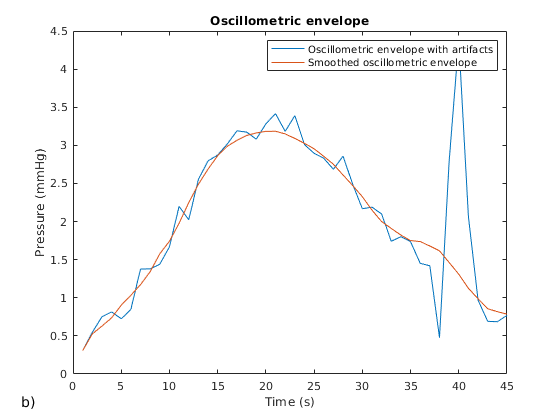

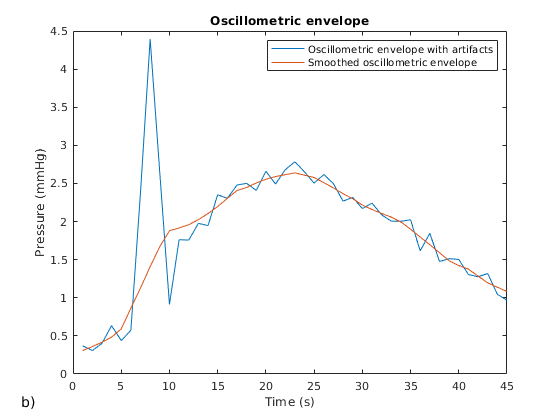

coef(1)=0.65;
coef(2)=0.61;
for i=1:100
  
    [P, Pa]=model_Babbs(R(i,3),R(i,4),R(i,1),R(i,2), fs, 0);
    % motion artifacts
    if motion==1
        z=zeros(1,length(P));
        start=floor(1000+floor(7500*rand(1)));  % add motion artifact at the random place on the pressure signal
        z(start:start+length(motion_signal)-1)=motion_signal;
        P=P+z+0.4*randn(1,length(P));
    end
    [cp,omw] = extract_omw(P, fs);
    [omwe, peak_ind] = envelope_detection(cp, omw, fs);
    % MAA algorithm with fixed coefficients
    [BP] = bp_max_amplitude(cp, coef, fs, omwe, peak_ind);
    SBP_est_fixed(i)=BP(1);
    DBP_est_fixed(i)=BP(2);
    
    
    % Max slope algorithms
    [BP, index] = bp_max_slope(cp, fs, omwe, peak_ind);
    SBP_est_slope(i)=BP(1);
    DBP_est_slope(i)=BP(2);
end

% Compute errors for all 3 algorithms
MAE_SBP=mean(abs(SBP_est_fixed-R(:,1)'));
STD_SBP=std(SBP_est_fixed-R(:,1)');
MAE_DBP=mean(abs(DBP_est_fixed-R(:,2)'));
STD_DBP=std(DBP_est_fixed-R(:,2)');
fprintf("MAA algorithm: MAE SBP=%f, std SBP=%f, MAE DBP=%f, std DBP=%f", MAE_SBP, STD_SBP, MAE_DBP, STD_DBP)
MAE_SBP=mean(abs(SBP_est_slope-R(:,1)'));
STD_SBP=std(SBP_est_slope-R(:,1)');
MAE_DBP=mean(abs(DBP_est_slope-R(:,2)'));
STD_DBP=std(DBP_est_slope-R(:,2)');
fprintf("MSA algorithm: MAE SBP=%f, std SBP=%f, MAE DBP=%f, std DBP=%f", MAE_SBP, STD_SBP, MAE_DBP, STD_DBP)

Exercise: In case no motion artifacts are simulated and no noise is added to the pressure curve, the results of MAA and MSA are satisfactory. Analyze the results in following cases:

- Include noise in the signal by writing P=P+0.4*randn(1,length(P)); Modify standard deviation and analyze the effects of the noise to the accuracy of the algorithms.

- Include motion artifacts (set motion =1) for 3 cases a) when motion artifacts can appear randomly anywhere like in the code above, b) when motion artifacts occur only in systolic region, c) when motion artifacts appear around MAP. 

- Modify the correlation coefficients for generated blood pressure and complieance values. Observe the results. 

## Functions

Algorithm for extracting the oscillometric waveform from the cuff pressure

function [cp,omw] = extract_omw(P, fs)
% Extract OMW
i=1:length(P);
w = warning ('off','all');
f=fit(i',P','poly3');
w = warning ('on','all');
cp=f(i);
%OMW
omw1 = P - cp';
cutoff = 10;
omw = lowpass(omw1, cutoff, fs);
end



Two blood pressure estimation algorithms are considered

- Extracting features from the pulses – these features over time are called oscillometric pulse indices (OPI).

- Interpolating OPIs to obtain the envelope and smoothing the envelope. The envelope of an oscillating signal is defined as a smooth curve outlining its extremes.

function [omwe, peak_ind] = envelope_detection(cp, omw, fs)
clear trough_ind start_ind;
%find OMW troughs
[peak_amp, peak_ind,~,~] = findpeaks(omw, 'MinPeakDistance', fs/(1.4), 'MinPeakHeight',0.2);
peak_distance = diff(peak_ind(1:end));
start_ind=peak_ind(1:end-1);
%end_ind=peak_ind(2:end-1)+round(peak_distance/3);
end_ind=peak_ind(2:end);

for i =1:length(start_ind)
    [~, ind] = min(omw(start_ind(i):end_ind(i)));
    trough_ind(i,:) = ind + start_ind(i) - 1;
end
peak_ind(1) = [];
trough_ind(1)=[];
%fix lengths and outliers
peak_ind(end) = [];

% Form the envelope based only on maximums
omwe = omw(peak_ind);
% Form envelope based on peak to peak
%omwe = omw(peak_ind)-omw(trough_ind);
omwe=smooth(medfilt1(omwe,7));
omwe_ind = peak_ind;
%for figure 6.13b
% figure
% plot(omw(peak_ind))
% hold on, plot(omwe)
% xlabel("Time (s)"), ylabel("Pressure (mmHg)")
% xlim([0,45])
% title('Oscillometric envelope')
% legend('Oscillometric envelope with artifacts', 'Smoothed oscillometric envelope')
% annonation_save('b)',"Fig5.13b.jpg", 1);
end

Maximum amplitude algorithm


function [BP] = bp_max_amplitude(cp, coef, fs, omwe, peak_ind)
[m,ind]=max(omwe);
BP(3)=cp(peak_ind(ind));
% Maximum amplitude
i1=find(m*coef(1)<omwe);
BP(1)=cp(peak_ind(i1(1)));
i2=find(m*coef(2)<omwe);
BP(2)=cp(peak_ind(i2(end)));
end

Maximum slope algorithm


function [BP, index] = bp_max_slope(cp, fs, omwe, peak_ind)
[m,ind]=max(omwe);
BP(3)=cp(peak_ind(ind));
index(3)=(ind);
omwe_sm=smooth(omwe);
omwe_diff=[0; diff(omwe_sm)];
[m1, i1]=max(omwe_diff(1:ind));
BP(1)=cp(peak_ind(i1));
index(1)=(i1);
[m2, i2]=min(omwe_diff(ind:end));
BP(2)=cp(peak_ind(i2+ind-1));
index(2)=(i2+ind-1);
end
%%


function [P, Pa]=model_Babbs(a,b,SBP, DBP, fs, plotting)
% This implementation follows closely the paper:
% Oscillometric measurement of systolic and diastolic blood pressures validated in a physiologic mathematical model
% by Charles F BabbsEmail author
% published in BioMedical Engineering OnLine, 2012, 11:56
% https://biomedical-engineering-online.biomedcentral.com/articles/10.1186/1475-925X-11-56


%Blood pressure to be simulated - please change systolic in the rangge 110
%to 140 and dia between 60 and 90

%%

r=0.12; % radius of the artery in cm
L=10;    % length of the artery covered by the cuff in cm
V0=200; % Volume of the cuff at the beginning in ml
delta_r=0.05; %  the brachial artery strain (?r/r) during a normal pulse is 4 percent for a blood pressure of 130/70 mmHg

%%
%Computing the parameters
PP= SBP-DBP; % pulse pressure
Pmid=0.5*(SBP+DBP); % mid pressure
P0=SBP+30; % start of cuff deflation

%a = 0.076; %log(0.1)/(-20); % stiffness coefficient change to 0.075 or 0.11 for very stiff arteries
rate=2.5; %rate of the cuff defflation
heart_rate=1; % in Hz
delta_Va=2*3.14*(r)*(delta_r*r)*L; %2*pi*r*delta_r*L change in volume

Cn= delta_Va/PP; % The normal pressure compliance for the artery segment is the volume change divided by pulse pressure

Va0=3.14*(r)^2*L; %The resting artery volume

%b=-log(Cn/(a*Va0))/Pmid; % another stiffness coefficient - equation (3) from the paper
%b=0.021;
% Model of the arterial pulse and its derivative
delta_T=1/fs;
t=0:delta_T:55;
omega=2*pi*heart_rate;
Pa=DBP+0.5*PP+0.36*PP*(sin(omega*t)+0.5*sin(2*omega*t)+0.25*sin(3*omega*t));
dP_dt=0.36*PP*omega*(cos(omega*t)+cos(2*omega*t)+0.75*cos(3*omega*t));
%%
% Volume vs transmural pressure - equation (4) from the paper
for i=1:length(t)
    Pt(i)=Pa(i)-P0+rate*t(i);
    if Pt(i)<0
        Va(i)=Va0*exp(a*Pt(i));
    else
        Va(i)=Va0*(1+(1-exp(-b*Pt(i)))*a/b);
    end
end
if plotting ==1
    figure; plot(Pt,Va,'o')
    legend('Volume(ml) vs Transmural pressure')
end
%%
% dVa_dt - equation (6)
for i=1:length(t)
    Pt(i)=Pa(i)-P0+rate*t(i); % transmural pressure
    if Pt(i)<0
        dVa_dt(i)=a*Va0*exp(a*Pt(i))*(dP_dt(i)+rate);
    else
        dVa_dt(i)=a*Va0*exp(-b*Pt(i))*(dP_dt(i)+rate);
    end
end
if plotting ==1
    figure; plot(P0-rate*t,dVa_dt) %plot(t,dVa_dt,'o-')
    legend('dVa/dt vs time')
end
%%
% Obtaining cuff pressure with the arterial pulse - equation (1a)
P(1)=P0;
Int_Va(1)=0;
for i=2:length(t)
    
    P(i)=P(i-1)-rate*delta_T+delta_T*(dVa_dt(i)*(P0+760-rate*t(i))/V0);
end
tspan = 0:delta_T:t(end);
if plotting ==1
    figure,
    hold on; plot(t,P) % and another way is manual integration
    legend('Cuff pressure vs time')
end
end
%%
